## The Report of Modeling Newton's Law of Cooling 

### `Introduction`

Newton’s Law of Cooling describes how a material changes temperature relative to its surroundings. The law expresses heat transfer as a differential equation that is dependent on time. The cooling rate is equal to the difference between the body temperature ($T_t$) and the surrounding temperature ($T_s$) multiplied by the cooling constant, k. The cooling constant k is dependent upon the material properties of the object. If a material is placed in an environment colder than its internal temperature the result will be a negative value, implying that the body is losing heat. If a material is placed in a warmer environment then the body will gain heat and there will be a positive result. This model of heat transfer also has its own limitations.

                                                                               
$$\frac{\textrm{dT}}{\textrm{dt}}=-k\left(T_t -T_s \right)$$


Where,

- $T_t$ = the temperature of the body at time t

- $T_s$ = the temperature of the surrounding

- $k$ = the positive cooling constant that depends on the area and nature of the surface of the body under consideration

### `Mathematical Theory`

The rate of cooling of the body is directly proportional to the temperature difference and the surface area exposed. Newton’s law of cooling is based on the Stefan Boltzmann law that describes the amount of radiation emitted from area A at a temperature T. 

                                                                                    
$$P=\epsilon \sigma AT^4$$


Where,

- $P$ = the total power radiated from an object

- $\varepsilon$ = the emissivity of material

- $\sigma$ = the Stefan-Boltzmann constant

- $A$ = the surface area

- $T$ = the absolute temperature

Simplifying this law into a constant, k, and including the varying temperature of the body yields Newton’s law of cooling. The constant k quantifies the ability of the object and surroundings to transfer heat.

Newton's law of cooling depends on an assumption that the object in the system has a low Biot number (Bi). The Biot number takes into account the object's heat transfer coefficient, characteristic length, and the thermal conductivity of the body. A Biot number less than 0.1 means that the object can be classified as “thermally thin”, meaning that temperature throughout the body of the object is uniform. This constant temperature throughout the volume of the object is required for Newton's law of cooling to hold true. If an object had a large Biot number the cooling would not have a stable pattern that could be easily modeled.

### `Analytical Solution`

Newton's Law of Cooling can be solved analytically using the separation of variables. The analytical solution is given by the equation:    

                
$$\frac{\textrm{dT}}{\textrm{dt}}=-k\left(T_t -T_s \right)$$


                                         $\int \frac{1}{T_t +T_s }=\int -k\;\textrm{dt}$, seperation of variables 

   
$$\ln \;\left|T_t -T_s \right|=-\textrm{kt}+c$$
    

    
$$\left|T_t -T_s \right|={e^c e}^{-\textrm{kt}}$$
   

    $T\left(t\right)={\;T}_s +Ae^{-\textrm{kt}}$ or  $T\left(t\right)={\;T}_s -Ae^{-\textrm{kt}}$

where,

- $t$= time

- $T\left(t\right)$ = the temperature of the body at time t

- $T_s$ = the temperature of the surrounding

- $A$= the constant

- $k$ = the cooling constant that depends on the area and nature of the surface of the body under consideration

### `Numerical Solution`

We'll implement various numerical methods to solve Newton's Law of Cooling numerically, including ODE23, ODE45, Forward Euler, and Backward Euler.

**ODE 23 & ODE 45**

ODE23 and ODE45 are MATLAB's built-in functions for solving nonstiff differential equations. ODE 23 uses a lower method while ODE 45 uses a medium method.ODE 23 can be more efficient than ODE45 at problems with crude tolerances, or in the presence of moderate stiffness. However, ODE 45 is usually more accurate than ODE 23.

**Forward Euler**

Forward Euler is a simple and explicit method for solving ordinary differential equations numerically. It approximates the derivative at each time step using a forward difference.

**Backward Euler**

Backward Euler is another numerical method for solving ordinary differential equations. It approximates the derivative at each time step using a backward difference.

Suppose that we placed water at 100 degree in Celsius and melting ice at 0 degree in Celsius in a room temperatured at 25 degree for 10 minutes with a cooling constant of water 1 and 100 time steps. Then we could plot all the numerical solutions. 

   
   
Cooling constant               k  = 1.000e+00   [1/min]  
   
Number of time steps           n  =  100  
   
Time interval for simulation   tsys  =   10   [min]  
   
Environmental temperature      Tenv  = 25.00   [degC]  
   
Initial temperature of system  T0  = 100.00   [degC]  


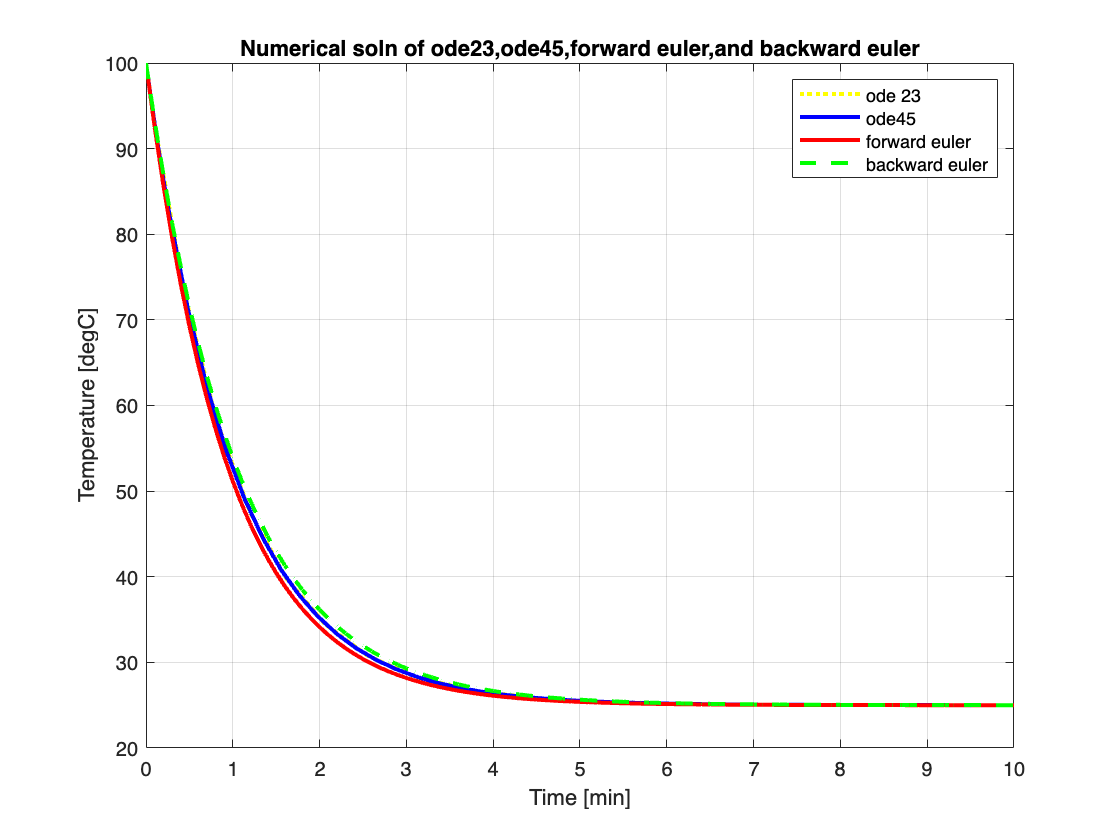

%Water
cooling_model(1,100,10,100,25,6);

   
   
Cooling constant               k  = 1.000e+00   [1/min]  
   
Number of time steps           n  =  100  
   
Time interval for simulation   tsys  =   10   [min]  
   
Environmental temperature      Tenv  = 25.00   [degC]  
   
Initial temperature of system  T0  = 0.00   [degC]  


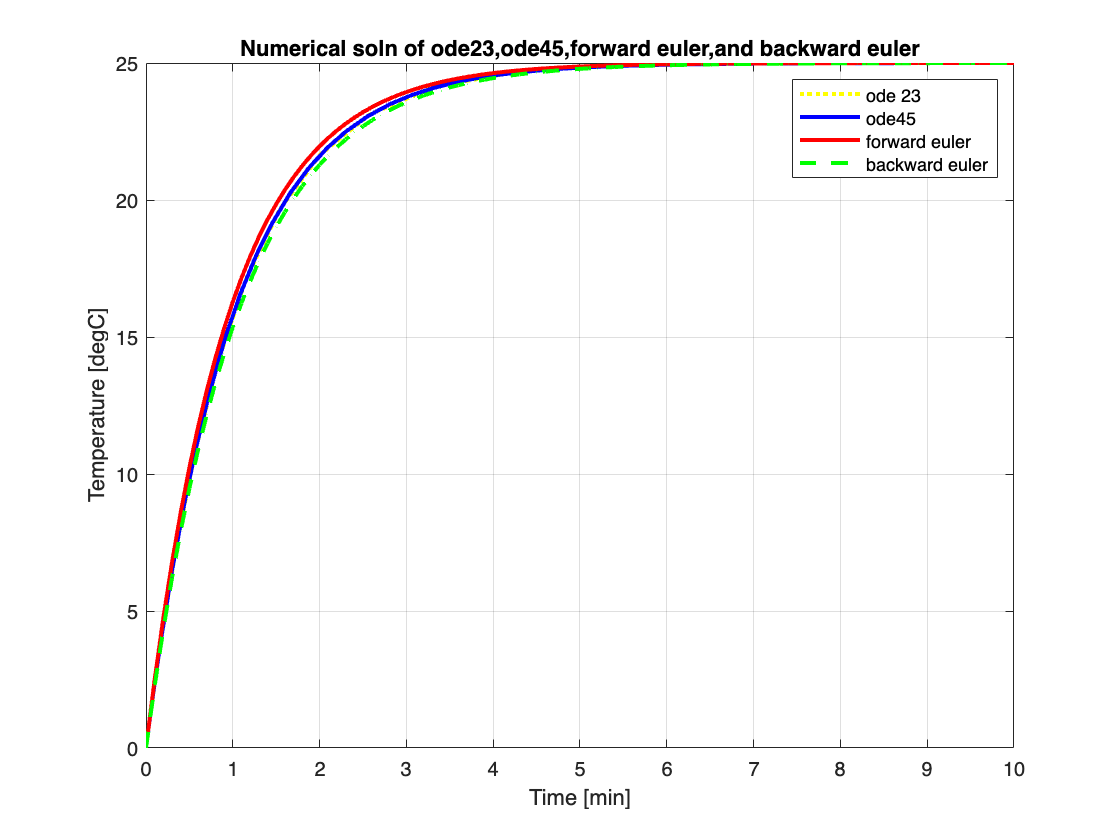

%Ice
cooling_model(1,100,10,0,25,6);

### `Validation with Real Data`

To validate our models, we'll compare the analytical and numerical solutions with real temperature data obtained from experiments or measurements.

We will use experimental data from the University of Georgia by Elizabeth Gieseking . For this exploration, Newton’s Law of Cooling was tested experimentally by measuring the temperature in three beakers of water as they cooled from boiling. The purpose of this investigation was to determine how well Newton’s law of cooling fit real data. This experiment involved three beakers of water. We will focus of the first contained 100 mL of water.This beakers held water at 100°C with a thermometer, which was kept in the beaker between measurements to prevent temperature lag. The temperature of the water in each beaker was taken every minute, in the same order. The ambient temperature for this research was 23 °C. 

Plot of the actual data is given below

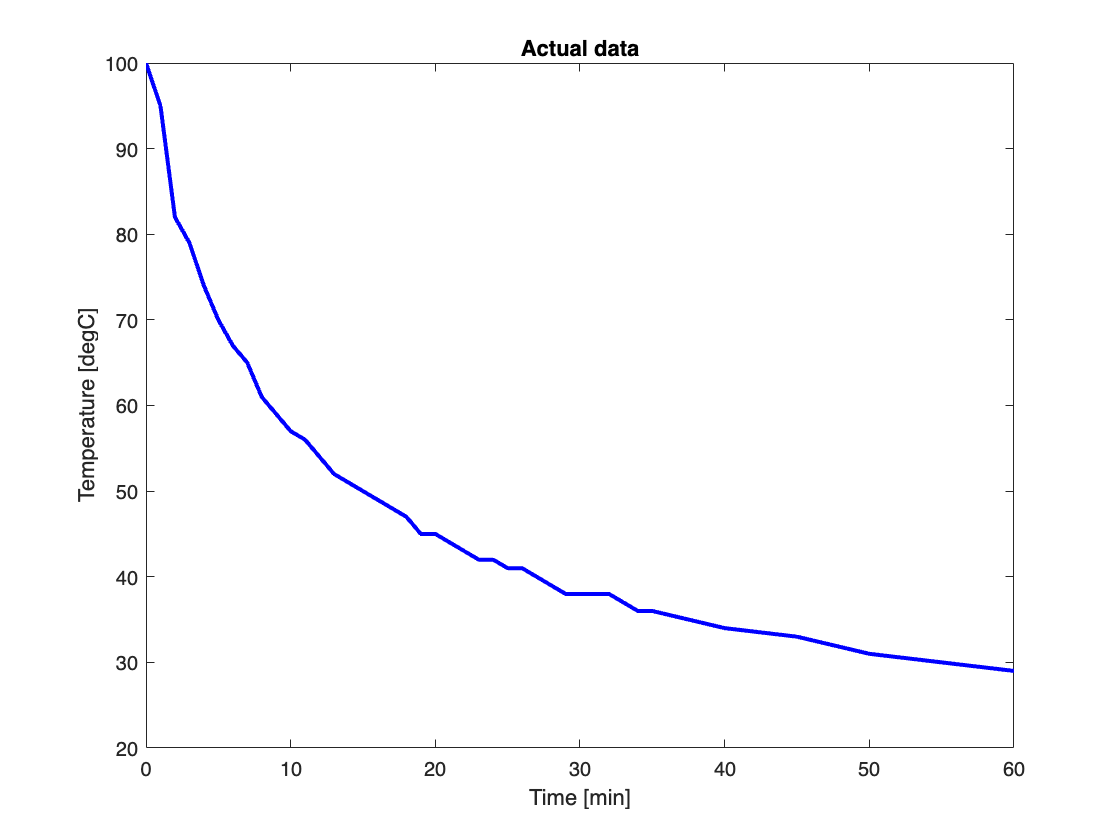

% Load experimental data from CSV file
data = readtable("real_data.csv");
time = data.Time; % Time vector
temperature = data.Temperature; % Temperature vector

figure;
plot(time, temperature, 'b-', 'LineWidth', 2);
xlabel('Time [min]');
ylabel('Temperature [degC]');
title('Actual data');

**Parameter estimation for cooling constant k**

A cooling constant k is required to model newtons law of cooling. We will estimate k by using fminsearch, which is  a matlab optimizater which can be used  to find the value of *k* that minimizes the difference between the experimental data and the analytical solution. 

We then calculate the R^2 value to evaluate the goodness of fit.

T0 = 100;
Ts = 23;

% Define the analytical function for Newton's Law of Cooling
model_function = @(k) Ts + (T0 - Ts) * exp(-k * time);

% Initial guess for the cooling constant k
initial_guess = 0.1; % Initial guess for k

% Perform optimization to estimate k
k_estimated = fminsearch(@(k) norm(temperature - model_function(k)), initial_guess);
% Evaluate model fit
temperature_fit = Ts + (T0 - Ts) * exp(-k_estimated * time);
R_squared = 1 - sum((temperature - temperature_fit).^2) / sum((temperature - mean(temperature)).^2);

% Display results
fprintf('Estimated Cooling Constant (k): %.4f\n', k_estimated);

Estimated Cooling Constant (k): 0.0665


fprintf('Coefficient of Determination (R^2): %.4f\n', R_squared);

Coefficient of Determination (R^2): 0.9198


### `Error Analysis `

To validate the accuracy and reliability of our numerical methods implemented, we’ll calculate and visualize the error between the numerical solutions and the analytical solution. We'll also 

We’ll use the absolute value and complex magnitude function (‘abs’) to calculate the error vector between the predicted temperatures obtained from each numerical method and the temperature obtained from the analytical solution at corresponding time steps. After the computation, we’ll visualize the error vectors by plotting them in a single figure for comparison. 

Assume that the cooling constant of a material 0.0665 for with 100 time steps. We placed a material at 100 degree in Celsius placed in a room temperature at 23 degree for an hour. 

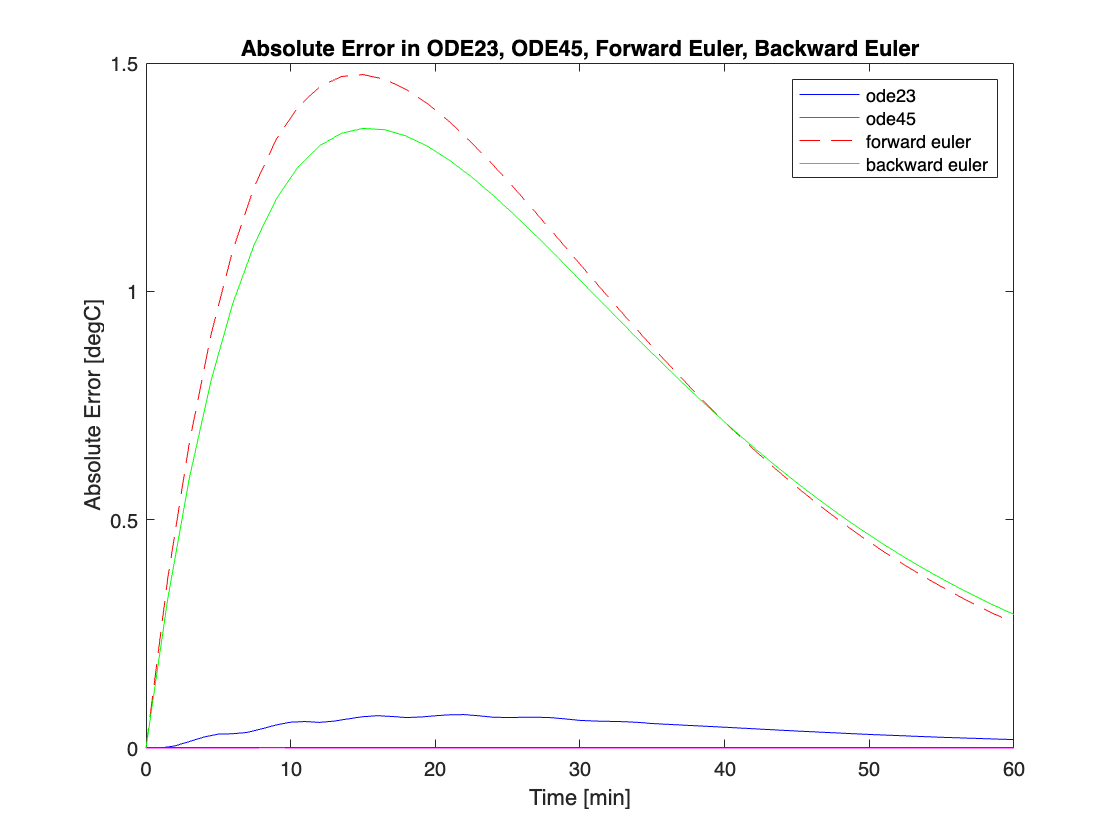

% Parameters
k = 0.0665;            % Cooling constant [1/min]
tsim = 60;             % Time interval for simulation [minutes]
Tsys = 100;            % Initial temperature of system [degC]
Tenv = 23;             % Temperature of surrounding environment [degC]

% Analytical Solution
% the constant A we defined in the Analytical Solution equals (Tsys - Tenv)
T_analytical = @(t) Tenv + (Tsys - Tenv) .* exp(-k .* t);

% Numerical Solutions 
f_ode = @(t, T) -k * (T - Tenv);

[t_ode23,T_ode23] = ode23(f_ode,time,Tsys);
[t_ode45, T_ode45] = ode45(f_ode, time, Tsys);
[t_forward_euler, T_forward_euler] = forward_euler_vec(f_ode, time, Tsys, 40); % We use the data time here to make sure all methods have the same rows
[t_backward_euler, T_backward_euler] = backward_euler(f_ode, time, Tsys, 40);

% Calculate the Absolute Error
abs_error_ode23 = abs(T_ode23 - T_analytical(t_ode23));
abs_error_ode45 = abs(T_ode45 - T_analytical(t_ode45));
abs_error_forward_euler = abs(T_forward_euler - T_analytical(t_forward_euler));
abs_error_backward_euler = abs(T_backward_euler - T_analytical(t_backward_euler));

% Plot the Absolute Error
figure
plot(t_ode23, abs_error_ode23, 'b-');
hold on
plot(t_ode45, abs_error_ode45, 'm');
hold on
plot(t_forward_euler,abs_error_forward_euler,'r--');
plot(t_backward_euler,abs_error_backward_euler,'g');
xlabel('Time [min]');
ylabel('Absolute Error [degC]');
legend('ode23','ode45','forward euler','backward euler')
title('Absolute Error in ODE23, ODE45, Forward Euler, Backward Euler');

Also, we will calculate the Coefficient of determination (R-squared) to indicate the proportionate amount of variation in the actual temperature explained both by the predicted temperatures obtained from each numerical method and the the analytical solution in the linear regression model. The larger the R-squared is, the more variability is explained by the linear regression model. Last but not least, we calculate the Root-mean-square-error to measure of the differences between true or predicted values.

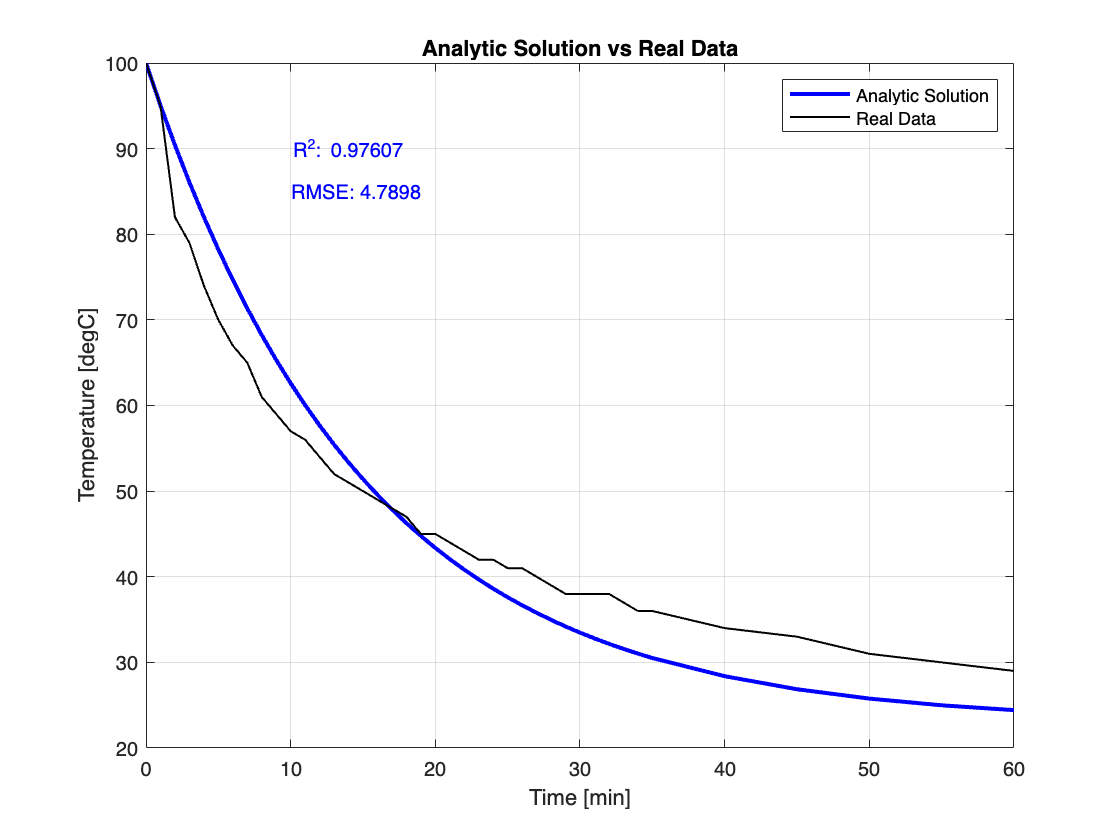

% Calculate R2 and RMSE for each solution
r2_ode23 = corr(T_ode23, temperature)^2;
rmse_ode23 = sqrt(mean((T_ode23 - temperature).^2));

r2_ode45 = corr(T_ode45, temperature)^2;
rmse_ode45 = sqrt(mean((T_ode45 - temperature).^2));

r2_forward_euler = corr(T_forward_euler, temperature)^2;
rmse_forward_euler = sqrt(mean((T_forward_euler - temperature).^2));

r2_backward_euler = corr(T_backward_euler, temperature)^2;
rmse_backward_euler = sqrt(mean((T_backward_euler - temperature).^2));

r2_analytic = corr(T_analytical(time), temperature)^2;
rmse_analytic = sqrt(mean((T_analytical(time) - temperature).^2));

% Plot the comparison between the analytical solution and the real data
figure
plot(time, T_analytical(time), 'b-', 'LineWidth', 2);
hold on;
plot(time, temperature, 'k-', 'LineWidth', 1);
xlabel('Time [min]');
ylabel('Temperature [degC]');
title('Analytic Solution vs Real Data');
legend('Analytic Solution', 'Real Data');
grid on;
hold off;
text(10, 90, ['R^2: ' num2str(r2_analytic)], 'Color', 'b');
text(10, 85, ['RMSE: ' num2str(rmse_analytic)], 'Color', 'b');

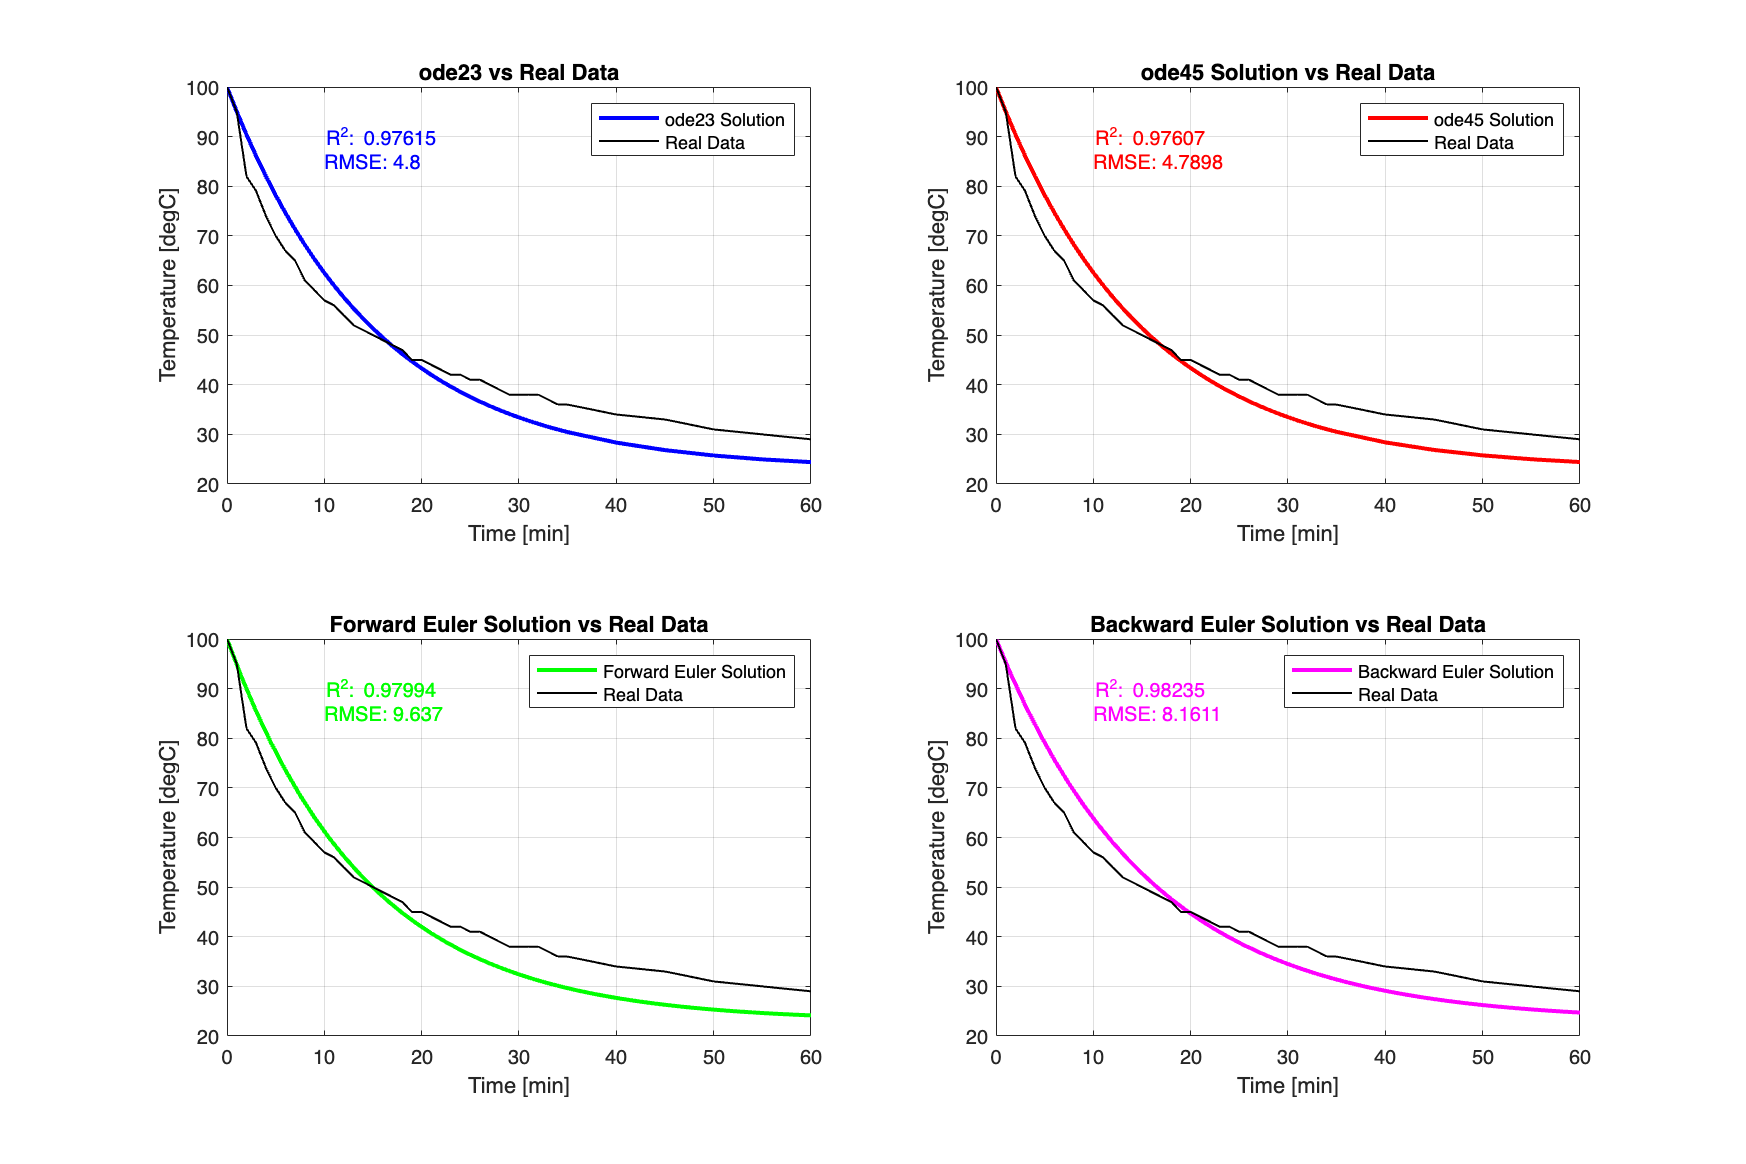

% Plot comparison of the numerical methods
figure('Position', [100, 100, 1200, 800]);

% ode 23 solution
subplot(2, 2, 1);
plot(t_ode23, T_ode23, 'b-', 'LineWidth', 2);
hold on;
plot(time, temperature, 'k-', 'LineWidth', 1);
xlabel('Time [min]');
ylabel('Temperature [degC]');
title('ode23 vs Real Data');
legend('ode23 Solution', 'Real Data');
grid on;
hold off;
text(10, 90, ['R^2: ' num2str(r2_ode23)], 'Color', 'b');
text(10, 85, ['RMSE: ' num2str(rmse_ode23)], 'Color', 'b');

% ode45 solution
subplot(2, 2, 2);
plot(t_ode45, T_ode45, 'r-', 'LineWidth', 2);
hold on;
plot(time, temperature, 'k-', 'LineWidth', 1);
xlabel('Time [min]');
ylabel('Temperature [degC]');
title('ode45 Solution vs Real Data');
legend('ode45 Solution', 'Real Data');
grid on;
hold off;
text(10, 90, ['R^2: ' num2str(r2_ode45)], 'Color', 'r');
text(10, 85, ['RMSE: ' num2str(rmse_ode45)], 'Color', 'r');

% Forward Euler solution
subplot(2, 2, 3);
plot(t_forward_euler, T_forward_euler, 'g-', 'LineWidth', 2);
hold on;
plot(time, temperature, 'k-', 'LineWidth', 1);
xlabel('Time [min]');
ylabel('Temperature [degC]');
title('Forward Euler Solution vs Real Data');
legend('Forward Euler Solution', 'Real Data');
grid on;
hold off;
text(10, 90, ['R^2: ' num2str(r2_forward_euler)], 'Color', 'g');
text(10, 85, ['RMSE: ' num2str(rmse_forward_euler)], 'Color', 'g');

% Backward Euler solution
subplot(2, 2, 4);
plot(t_backward_euler, T_backward_euler, 'm-', 'LineWidth', 2);
hold on;
plot(time, temperature, 'k-', 'LineWidth', 1);
xlabel('Time [min]');
ylabel('Temperature [degC]');
title('Backward Euler Solution vs Real Data');
legend('Backward Euler Solution', 'Real Data');
grid on;
hold off;
text(10, 90, ['R^2: ' num2str(r2_backward_euler)], 'Color', 'm');
text(10, 85, ['RMSE: ' num2str(rmse_backward_euler)], 'Color', 'm');

### `Limitations/Scope`

Although Newton's law of cooling is applicable within certain settings, it also has many limitations that constrain this model. The law assumes that the surrounding temperature remains constant as the object's temperature fluctuates. The object's change in temperature also must have no significant impact on the temperature of the environment. If the object's temperature influences that of the environment substantially then the law will not hold. During the mathematical derivation for the law, it was presumed that the temperature difference between the object and the environment did not differ greatly. This condition simplifies the cooling law mathematically but also limits the model's versatility and ability to be applied in real-world applications. 

Since Newton's law of cooling is based on Stefan Boltzmann's law of radiation the heat lost or gained by the object must only be due to radiation. This can be through microwaves, visible light, or infrared radiation. The model does not take into account heat lost by conduction or convection. Conduction refers to the transfer of heat through direct contact and convection refers to the movement of heat through fluid or gas motion. Although Newton’s law has been shown to be accurate in cases with conduction or convection when there is a small change in temperature the model was not designed with these heat transfers in mind. Although Newton's law of cooling can be validated with data in the outside world many of these conditions are not met. Although Newton's law of cooling is severely limited it can be used for a basic understanding of radiation heat transfer within a controlled system.     

### `Conclusion `

In this project, we modeled Newton’s Law of Cooling using both analytical and numerical methods in MATLAB. We implemented the analytical solution and various numerical methods, including ODE23, ODE45, Forward Euler, and Backward Euler. We also validated our models using real temperature data.

### `Reference`

“Newton’s Law of Cooling - Derivation, Formulas, Solved Examples.” *BYJUS*, BYJU’S, 28 Aug. 2023, byjus.com/jee/newtons-law-of-cooling/. 

“Newton’s Law of Cooling, An Experiimental Investigation.” Elizabeth Geiseking, http://jwilson.coe.uga.edu/EMAT6680Fa2014/Gieseking/Exploration%2012/Newton's%20Law%20of%20Cooling.htm.

“Limitations of the Newton’s Law of Cooling.” *Unacademy*, 18 Apr. 2022, unacademy.com/content/upsc/study-material/chemistry/limitations-of-the-newtons-law-of-cooling/. 